rho = 0.02;
l_0 = 0.5;
g_o_rods = {Pose2.hat([0; rho; 0]), Pose2.hat([0; 0; 0]), Pose2.hat([0; -rho; 0])};

g_o = Pose2.hat([0; 0; -pi/2]);
seg = ArmSegment(Pose2, g_o, g_o_rods, l_0);
seg.set_mechanics(GinaMuscleMechanics(l_0), 2);
seg.set_mechanics(BasicPolyBellowMechanics(l_0), [1, 3]);

p = [30; 10; 0];
Q = [0; -5; 0];

g_circ_right = [1.1 * l_0; 0; 0.5];

seg.g_circ_right = g_circ_right;
F = seg.get_forces(p);
e = seg.get_strains();

if true
    F
    e
end

F =    37.0184
 -104.7807
   -2.3549


e =     0.0800
    0.1000
    0.1200


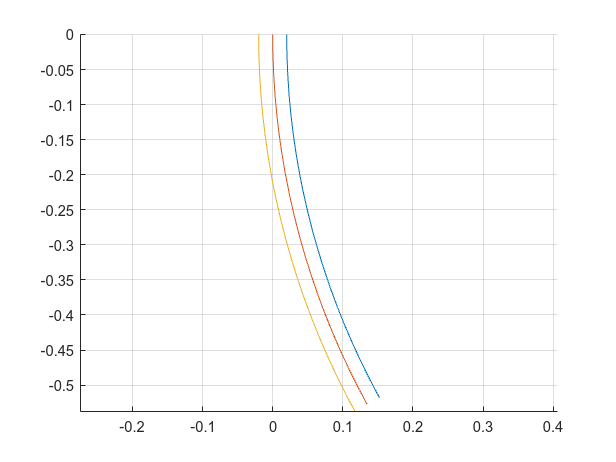

Plotter2D.plot_arm_segment(seg, axes(figure()));
grid on

% Get F as a function of g_circ_right
e_range = [-0.3, 0.3];
k_range = [-3, 3];

% Generate a list of input g_circ_right's
N_samples = 100;
v_l = linspace(l_0 * (1+e_range(1)), l_0 * (1+e_range(2)), N_samples);
v_kappa = linspace(k_range(1), k_range(2), N_samples);

cell_g_circ_right = cell(N_samples, N_samples);
cell_actuator_forces = cell(N_samples, N_samples);

cell_internal_forces = cell(N_samples, N_samples);
cell_hsv = cell(N_samples, N_samples);
for i = 1 : length(v_l)
    for j = 1:length(v_kappa)
        g_circ_right_i = [v_l(i); 0; v_kappa(j)];
        cell_hsv{i, j} = [i/length(v_l) * 0.8; j/length(v_kappa) * 0.75 + 0.25; 1];

        cell_g_circ_right{i, j} = g_circ_right_i;
        actuator_forces = seg.get_forces(p, g_circ_right_i);
        cell_actuator_forces{i, j} = actuator_forces;
        cell_internal_forces{i, j} = seg.mat_A * actuator_forces;
    end
end

mat_actuator_forces = [cell_actuator_forces{:}];
mat_internal_forces = [cell_internal_forces{:}];
mat_hsv = [cell_hsv{:}];
mat_rgb = hsv2rgb(mat_hsv');

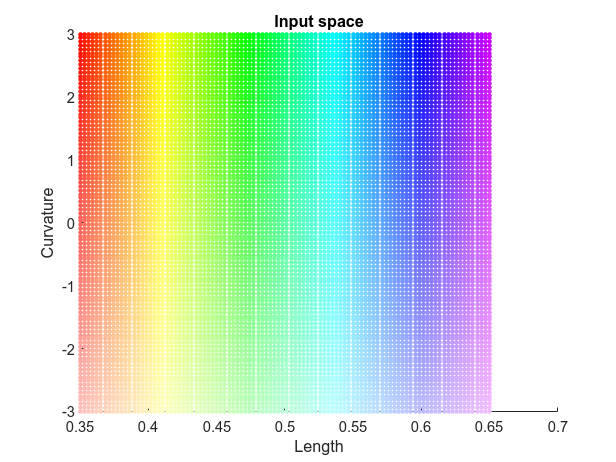

mat_g_circ_right = [cell_g_circ_right{:}];
figure()
scatter(mat_g_circ_right(1, :), mat_g_circ_right(3, :), 10, mat_rgb, 'o', 'filled')
title("Input space")
xlabel("Length")
ylabel("Curvature")

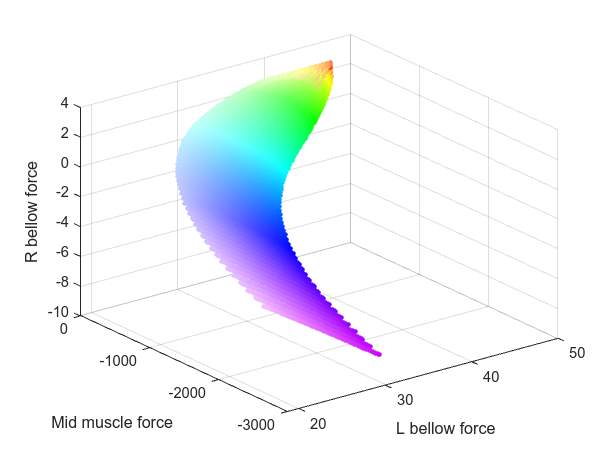

figure()
scatter3(mat_actuator_forces(1, :), mat_actuator_forces(2, :), mat_actuator_forces(3, :), 10, mat_rgb, 'filled', 'o')
xlabel("L bellow force");
ylabel("Mid muscle force");
zlabel("R bellow force");

% Find the sub-space of valid equilibrium actuator force vectors
% ie, F such that AF = Q

% A hypothetical external reaction force/moment
Q_ext = [-3; 0; -1];

% Solve for Q_internal = AF such that Q_ext + Q_internal = 0
% ie, AF = -Q_ext

F_pinv = pinv(seg.mat_A) * -Q_ext;

if true
    disp(seg.mat_A * F_pinv)
    disp(-Q_ext)
end

    3.0000
         0
    1.0000


     3
     0
     1



% Sample the space of valid force balances
u = linspace(-50, 50, 100);

equil_F = null(seg.mat_A) .* u + F_pinv;

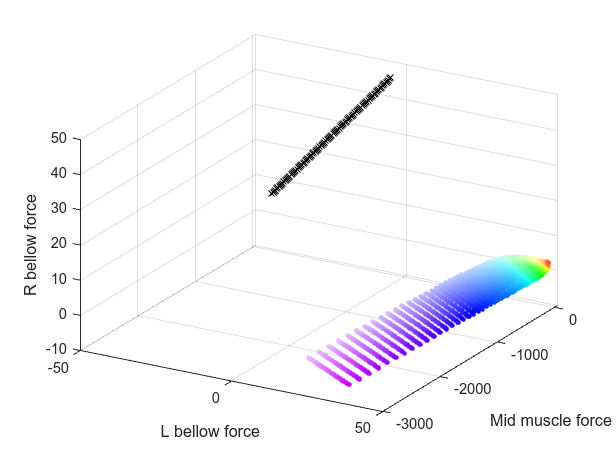

ax = axes(figure());
hold(ax, "on")
scatter3(ax, mat_actuator_forces(1, :), mat_actuator_forces(2, :), mat_actuator_forces(3, :), 10, mat_rgb, 'filled', 'o')
scatter3(ax, equil_F(1, :), equil_F(2, :), equil_F(3, :), 'kx');
xlabel("L bellow force");
ylabel("Mid muscle force");
zlabel("R bellow force");
grid on
view(30, 30)

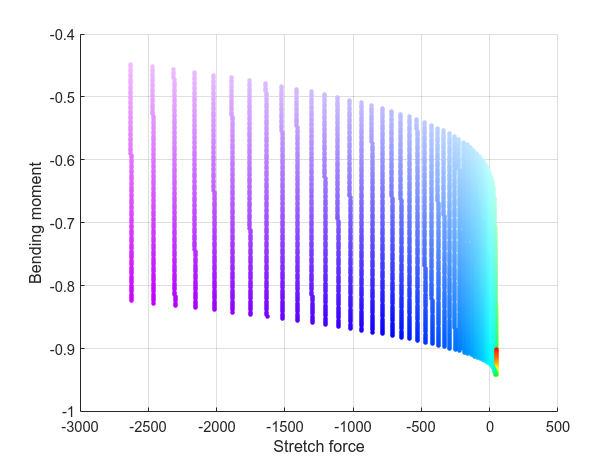

figure()
scatter(mat_internal_forces(1, :), mat_internal_forces(3, :), 10, mat_rgb, 'o', "filled");
grid on
xlabel("Stretch force")
ylabel("Bending moment")